## Section-wise Interpolation

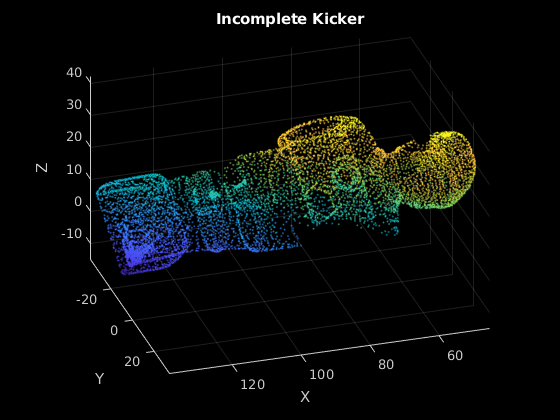


clear all; clf; clc;

points = readtable("Kickerfigur_incomplete.xlsx");
points = points{:,1:3};

pcshow(points,"MarkerSize",7,"VerticalAxis","Z")
title("Incomplete Kicker");
xlabel("X")
ylabel("Y")
zlabel("Z")


points_aligned = rotatePointCloudAlongZ(points, "x","",0);

gridStep = 1;
points_aligned = pointCloud(points_aligned);
points_downsampled = pcdownsample(points_aligned, "gridAverage", gridStep);
points_downsampled = points_downsampled.Location;

%%========= 1
points_aligned= sortrows(points_downsampled, 3);

x = points_aligned(:,1);
y = points_aligned(:,2);
z = points_aligned(:,3);


ax1 = subplot(1,2,1)

ax1 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.3347 0.8150]
            Units: 'normalized'

  Show all properties


pcshow(points_aligned,"MarkerSize",7,"VerticalAxis","Z")
title("Downsampled Kicker");
xlabel("X")
ylabel("Y")
zlabel("Z")
hold on

limz = [min(z)-1 min(z)-1 
        max(z)+1 max(z)+1];
limy = [min(y)-1 max(y)+1 
        min(y)-1 max(y)+1];
limx = [0 0 
        0 0];

plot3(0, 0, 0,'o','color','w',"MarkerSize",7,'MarkerFaceColor',"white")
surf(limx, limy, limz, "LineStyle","-", "FaceAlpha",0.25,"EdgeColor",[1,1,1] )
hold off

%%========= 2
ax2 = subplot(1,2,2)

ax2 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.5703 0.1100 0.3347 0.8150]
            Units: 'normalized'

  Show all properties


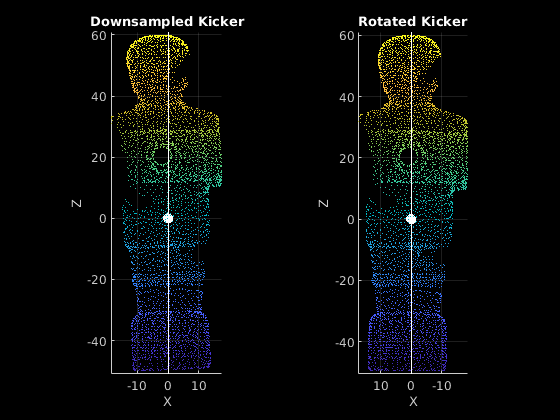

points_rotY = rotatePointCloudAlongZ(points, "x","y",3);
points_aligned = pointCloud(points_rotY);
points_downsampled = pcdownsample(points_aligned, "gridAverage", gridStep);
points_downsampled = points_downsampled.Location;
points_rotY = sortrows(points_downsampled, 3);
x = points_rotY(:,1);
y = points_rotY(:,2);
z = points_rotY(:,3);

pcshow(points_rotY,"MarkerSize",7,"VerticalAxis","Z")
title("Rotated Kicker");
xlabel("X")
ylabel("Y")
zlabel("Z")
hold on

limz = [min(z)-1 min(z)-1 
        max(z)+1 max(z)+1];
limy = [min(y)-1 max(y)+1 
        min(y)-1 max(y)+1];
limx = [0 0 
        0 0];

plot3(0, 0, 0,'o','color','w',"MarkerSize",7,'MarkerFaceColor',"white")
surf(limx, limy, limz, "LineStyle","-", "FaceAlpha",0.25,"EdgeColor",[1,1,1] )
hold off

subplot(1,2,1)
view([0 0])


subplot(1,2,2)
view([-180 0])


points_cut = points_rotY(:,:)

points_cut =    -4.8883    1.0358  -49.5615
    0.5022    1.0023  -49.5537
   -2.1517    0.1427  -49.5415
   -7.9004    2.4823  -49.5253
   -9.2793    2.4129  -49.5138
   -4.1312    2.1257  -49.5107
    0.2802   -0.2985  -49.5094
   -2.6623    1.7734  -49.5075
    0.9944    1.7529  -49.5045
   -7.6607    1.7677  -49.5042


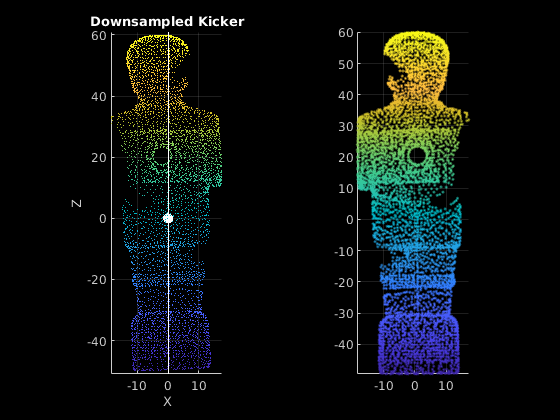


pcshow(points_cut,"MarkerSize",14)
view([0.0 0.0])


[r,c] = size(points_cut) ;
points_cut_cloud = pointCloud(points_cut);



points_new = [];
for k= 1:r
        point = points_cut(k,:);
        point(1) = -1*point(1);
        
        points_cut = [  points_cut
                    [point(1) point(2) point(3)]
                 ];
        
        

end


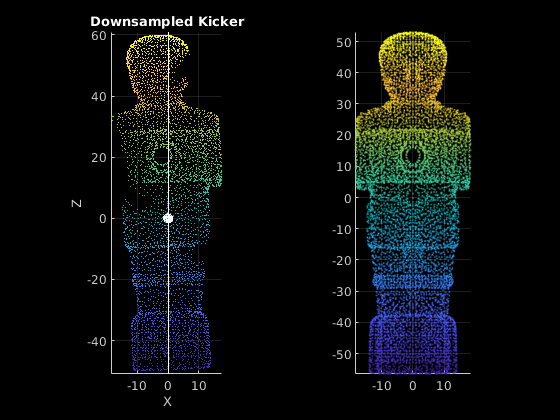


points_cut = pointCloud(points_cut);
points_cut = pcdownsample(points_cut, "gridAverage", 1);
points_cut = points_cut.Location;
points_cut = rotatePointCloudAlongZ(points_cut, "x","",0);
pcshow(points_cut)


points_cut = pointCloud(points_cut);
points_cut = pcdownsample(points_cut, "gridAverage", 0.5);
points_cut = points_cut.Location;
points_cut = rotatePointCloudAlongZ(points_cut, "x", "",0);
pcshow(points_cut)





subplot(1,2,2)
view([0 0])